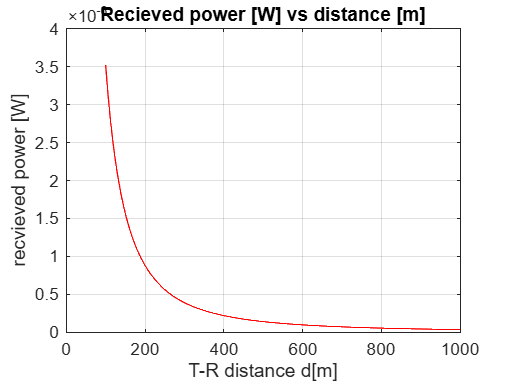

fc = 900*10^6;
 lambda = 3*10^8/fc;
 Pt = 50;
 Gt= 1;
 Gr =1;
 L = 1;
 d0 =100;
 d = 100:10^3;
 % Calculate received power at reference distance (d0)
 Pr_d0 = Pt * Gt * Gr * lambda^2 / (16 * pi^2 * d0^2 * L);
 Pr_d0_dBm = 10 * log10(Pr_d0 * 1000);  % Convert to dBm
 Pr_d0_dBW = 10 * log10(Pr_d0);  % Convert to dBW
 % Calculate received power at varying distances (d)
 Pr_d = Pt * Gt * Gr * lambda^2 ./ (d.^2 * 16 * pi^2 * L);
 Pr_d_dBm = Pr_d0_dBm + 20 * log10(d0 ./ d);
 Pr_d_dBW = Pr_d0_dBW + 20 * log10(d0 ./ d);
 PL = -10*log(Gr*Gt*lambda^2./(16*pi^2*d.^2));
 figure(1)
 plot(d,Pr_d,'r')
 grid on
 title('Recieved power [W] vs distance [m]')
 xlabel('T-R distance d[m]')
 ylabel('recvieved power [W]')

 figure(2)
 1

ans = 1

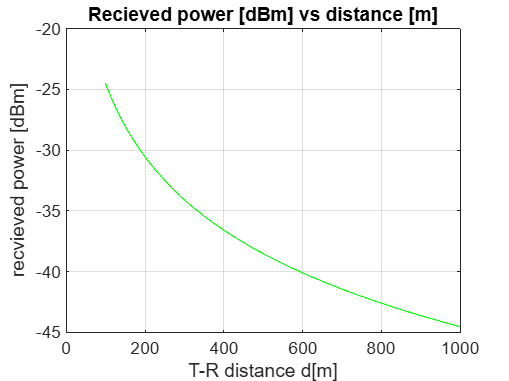

plot(d,Pr_d_dBm,'g')
 grid on
 title('Recieved power [dBm] vs distance [m]')
 xlabel('T-R distance d[m]')
 ylabel('recvieved power [dBm]')

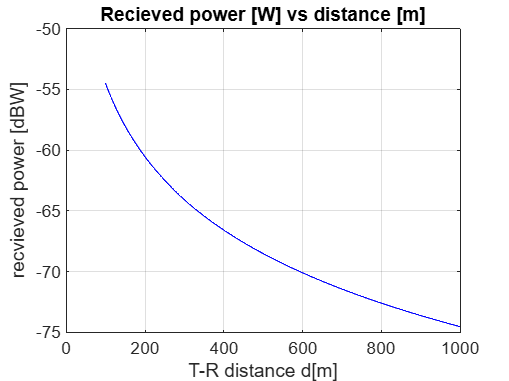

 figure(3)
 plot(d,Pr_d_dBW,'b')
 grid on
 title('Recieved power [W] vs distance [m]')
 xlabel('T-R distance d[m]')
 ylabel('recvieved power [dBW]')

 figure(3)
 plot(d,Pr_d_dBW,'b')
 grid on
 title('Recieved power [W] vs distance [m]')
 xlabel('T-R distance d[m]')
 ylabel('recvieved power [dBW]')

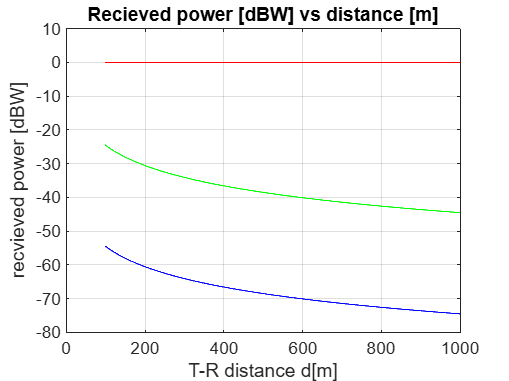

figure(5)
 plot(d,Pr_d,'r')
 grid on
 title('Recieved power [W] vs distance [m]')
 xlabel('T-R distance d[m]')
 ylabel('recvieved power [W]')
 hold on
 plot(d,Pr_d_dBm,'g')
 grid on 
title('Recieved power [dBm] vs distance [m]')
 xlabel('T-R distance d[m]')
 ylabel('recvieved power [dBm]')
 plot(d,Pr_d_dBW,'b')
 grid on 
title('Recieved power [dBW] vs distance [m]')
 xlabel('T-R distance d[m]')
 ylabel('recvieved power [dBW]')